# ORIENTASI KINEMATIK

# 1. Axis-Angle Rotation

Mendeklarasikan varphi ($\left.\varphi \right)$, theta ($\theta$) dan phi ($\phi$) sebagai simbol dari nilai sudut/angle.

clear
syms varphi phi theta

Dasar mencari Axis-Angle Rotation adalah Basic Mathematical Tools: Rotation Matrix yang sudah dipelajari sebelumnya. Notasi matriks rotasi dasar berikut menunjukkan transformasi rotasi terhadap sumbu Z sejauh $\varphi$:

Azvarphi = [cos(varphi) -sin(varphi) 0; sin(varphi) cos(varphi) 0; 0 0 1]

Notasi matriks rotasi dasar berikut menunjukkan transformasi rotasi terhadap sumbu Y sejauh $\theta$:

Aytheta = [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)]

Notasi matriks rotasi dasar berikut menunjukkan transformasi rotasi terhadap sumbu Z sejauh $\phi$:

Azphi = [cos(phi) -sin(phi) 0; sin(phi) cos(phi) 0; 0 0 1]

Notasi matriks rotasi dasar berikut menunjukkan transformasi rotasi terhadap sumbu Y sejauh $\theta$:

Aymintheta = [cos(-theta) 0 sin(-theta); 0 1 0; -sin(-theta) 0 cos(-theta)]

Notasi matriks rotasi dasar berikut menunjukkan transformasi rotasi terhadap sumbu Z sejauh $\phi$:

Azminvarphi = [cos(-varphi) -sin(-varphi) 0; sin(-varphi) cos(-varphi) 0; 0 0 1]

Dari notasi matriks rotasi diatas dapat dicari sebuah transformasi matrix $R_B^G$ yang memetakkan koordinat dilokal frame B(O$xyz$) ke koordinat tujuan global frame G(O.XYZ) sebagai berikut : 

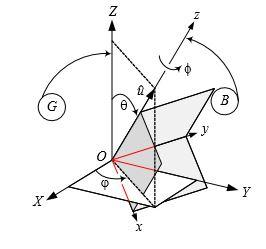

$R_B^G$ = ${R_G^B }^{-1}$= ${R_G^B }^T$ = $R_{\hat{u,} \phi }$

= Transpose [$A_{z,-\varphi } ,A_{y,-\theta } ,A_{z,\phi } ,A_{y,\theta } ,A_{z,\varphi }$]

gRb = transpose(Azminvarphi*Aymintheta*Azphi*Aytheta*Azvarphi)
syms u1 u2 u3

eqn = subs(gRb, sin(varphi), u2/sqrt(u1^2+u2^2))
eqn = subs(eqn, sin(theta), sqrt(u1^2+u2^2))
eqn = subs(eqn, sin(theta)*sin(varphi), u2)
eqn = subs(eqn, cos(varphi), u1/sqrt(u1^2+u2^2))
eqn = subs(eqn, cos(theta), u3)
eqn = subs(eqn, sin(theta)*cos(varphi), u1)
eqn = subs(eqn, sqrt(u1^2+u2^2+u3^2),1)
syms versphi
gRb = subs(eqn,1-cos(phi), versphi)